# Example of applications for the function binAveraging

## Case of a broad-banded power spectral density smoothed by bin averaging

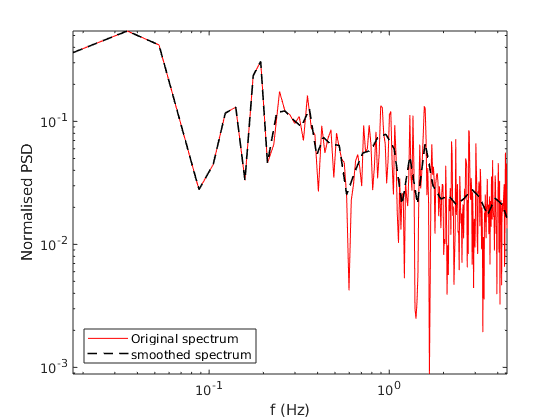

clearvars;close all;clc;
load('PSD_velocity.mat','u','t')


fs = 1/median(diff(t));
f0 = 1/t(end);
[Su,f] = pwelch(detrend(u),512,256,512,fs);

M=60;

newF0 = logspace(log10(f(2)*0.8),log10(f(end)*1.1),M);

[newSu,newF] = binAveraging(Su,f,'newX',newF0);

clf;close all;
figure

loglog(f,f.*Su./var(u),'r');
hold on
loglog(newF,newF.*newSu./var(u),'k--','linewidth',1.2)
legend('Original spectrum','smoothed spectrum','location','southwest')
axis tight
xlabel('f (Hz)')
ylabel('Normalised PSD')

set(gcf,'color','w')

## Case of a scatter plot with 10 bins and an errorbar showing 2x the standard deviation

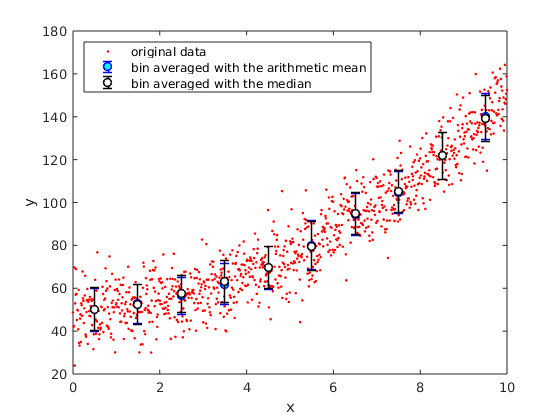


x = linspace(0,10,1000);

y = 50 + x.^2 + 10*randn(1,numel(x));

[newY,newX,dispersionY] = binAveraging(y,x,'Nbin',10,'dispersion','std');
[newY2,newX2,dispersionY2] = binAveraging(y,x,'Nbin',10,'dispersion','std','averaging','median');

figure
plot(x,y,'r.')
hold on
errorbar(newX,newY,dispersionY,'bo','markerfacecolor','c','linewidth',1.2)
errorbar(newX2,newY2,dispersionY2,'ko','markerfacecolor','w','linewidth',1.2)
legend('original data','bin averaged with the arithmetic mean','bin averaged with the median','location','northWest')
xlabel('x')
ylabel('y')

set(gcf,'color','w')

## Case of a scatter plot with a bin width of 1 and an errorbar using percentiles

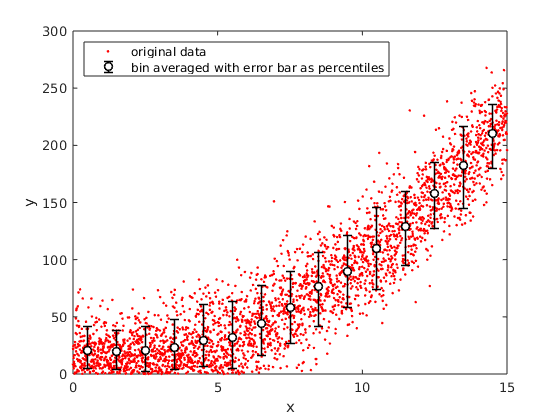


x = linspace(0,15,3000);

y = abs(x.^2 + 25*randn(1,numel(x)));

[newY,newX,dispersionY] = binAveraging(y,x,'binWidth',1,'dispersion','decile_10_90');

figure
plot(x,y,'r.')
hold on

NEG = newY-dispersionY(:,1); % lower error bar (10th percentile)
POS = dispersionY(:,2) - newY; % upper error bar (90th percentile)
errorbar(newX,newY,NEG,POS,'ko','markerfacecolor','w','linewidth',1.2)
legend('original data','bin averaged with error bar as percentiles','location','northWest')
xlabel('x')
ylabel('y')

set(gcf,'color','w')